% Script: extraer_morfometria_conos.m
% Objetivo: Extraer parámetros morfométricos desde archivos .xls de MORVOLC

clear; clc;

% 📂 Ruta a la carpeta que contiene los archivos .xls
carpeta = 'C:\Users\56931\Desktop\Proyecto\Data_final';  % <-- Cambiar a la ruta local
archivos = dir(fullfile(carpeta, '*.xls'));
n = length(archivos);

% 🧱 Inicializar variables
nombres = strings(n,1);
Wb = zeros(n,1);     % Basal Width
H = zeros(n,1);      % Maximum Height
Vol = zeros(n,1);    % Maximum Volume
Slope = zeros(n,1);  % Flank Mean Slope

for i = 1:n
    archivo = fullfile(carpeta, archivos(i).name);
    nombres(i) = archivos(i).name;

    % Leer hoja "Size_Parameters"
    sizeData = readcell(archivo, 'Sheet', 'Size_Parameters');

    % Buscar y extraer valores
    for j = 1:size(sizeData,1)
        if ischar(sizeData{j,1}) || isstring(sizeData{j,1})
            switch strtrim(sizeData{j,1})
                case 'Basal Width (m):'
                    Wb(i) = sizeData{j,2};
                case 'Maximum Height (m):'
                    H(i) = sizeData{j,2};
                case 'Maximum Volume (m3):'
                    Vol(i) = sizeData{j,2};
            end
        end
    end

    % Leer hoja "Slope_Parameters"
    slopeData = readcell(archivo, 'Sheet', 'Slope_Parameters');
    for j = 1:size(slopeData,1)
        if ischar(slopeData{j,1}) || isstring(slopeData{j,1})
            if strcmp(strtrim(slopeData{j,1}), 'Flank Mean Slope (deg.):')
                Slope(i) = slopeData{j,2};
            end
        end
    end
end

% 📊 Crear tabla de resultados
tabla = table(nombres, Wb, H, Vol, Slope);
disp(tabla);

                  nombres                    Wb        H          Vol        Slope 
    ___________________________________    ______    ______    __________    ______

    "MorVolc_SaveXLS_HauEpa.xls"            182.9    36.637    4.9167e+05    22.537
    "MorVolc_SaveXLS_MKoua.xls"            271.53    28.343    8.2949e+05     11.91
    "MorVolc_SaveXLS_MMahatua.xls"         219.68    20.504    5.2685e+05    12.239
    "MorVolc_SaveXLS_MOri.xls"              103.1    10.889         44138    16.756
    "MorVolc_SaveXLS_MTeOirena.xls"        399.89    79.049    5.2607e+06    19.691
    "MorVolc_SaveXLS_MakaHoru.xls"          190.5    26.094    3.8201e+05    30.496
    "MorVolc_SaveXLS_MakaHoruE.xls"        184.98     25.11    4.0239e+05    28.205
    "MorVolc_SaveXLS_MaungaKuma.xls"       226.79    25.986    6.1218e+05

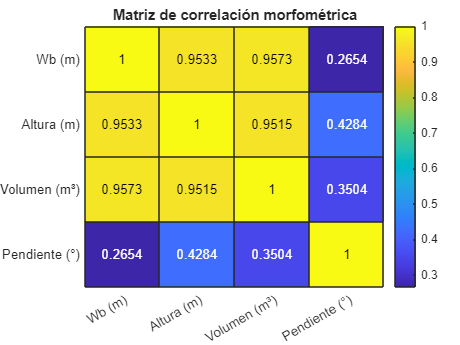


% 💡 Guardar tabla en Excel
ruta_guardado = 'C:\Users\56931\Desktop\Proyecto\Resultados';
writetable(tabla, fullfile(ruta_guardado, 'resumen_parametros_conos.xlsx'));


% 🔎 Calcular y graficar correlaciones
datos = [Wb, H, Vol, Slope];
labels = {'Wb (m)', 'Altura (m)', 'Volumen (m³)', 'Pendiente (°)'};
R = corrcoef(datos, 'Rows','complete');

figure;
heatmap(labels, labels, R, 'Colormap', parula, 'ColorbarVisible','on');
title('Matriz de correlación morfométrica');